# **Implementation of Viterbi Decoding**

###         A) Viterbi Decoder

###         B) MATLAB Viterbi 

### **A) Viterbi Decoder.**

- **In order to design a Viterbi code for the encoded message, the Generative polynomials are needed.**

- **g = [1 1 1 1 ; 1 1 0 1] based on the below figure.**

- **After that, the table with path metric is constructed.**

- **The table is filled based on the hamming distances.**

- **Finally, the backward bits identification is performed to find the exact decoded message.**

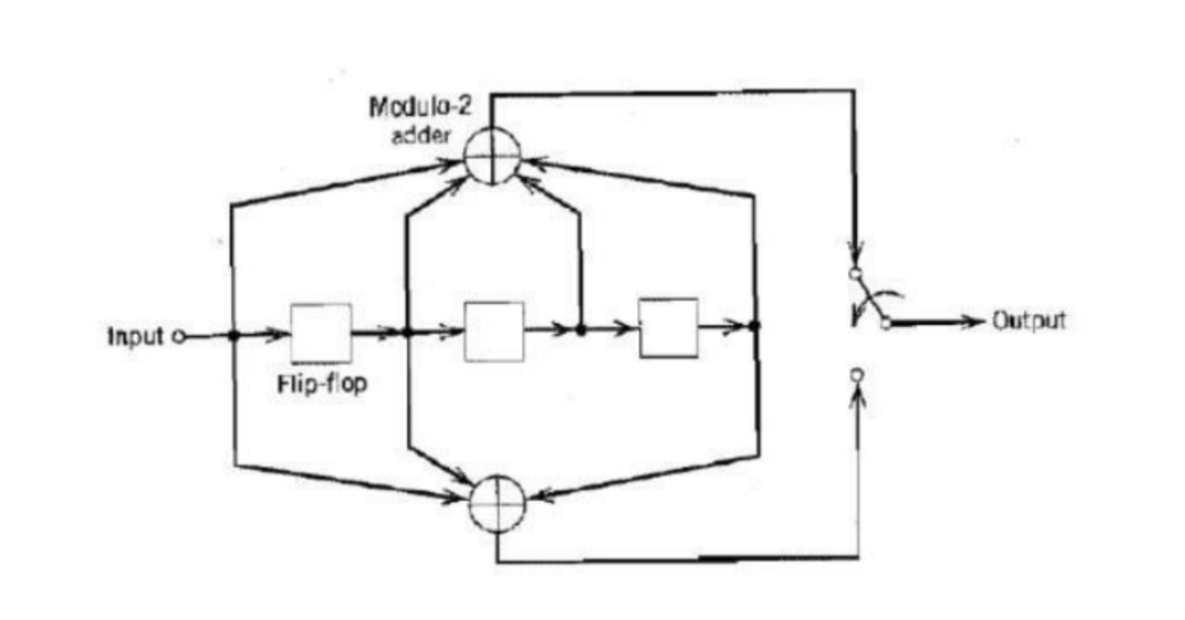

- **Possible States with inputs and outputs:**

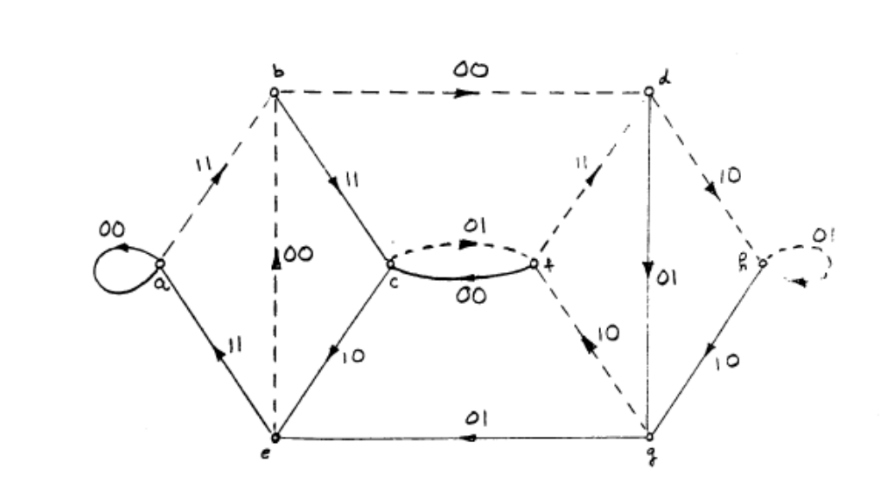

clear;
close all;
clc;

% Generative polynomials
gm1 = [1 1 1 1]; 
gm2 = [1 1 0 1];
g = [gm1; gm2];
% Received Encoded Message
received_message = [1 1 1 1 0 1 0 1 1 0 1 0];
decoded_message = [];

fprintf("Encoded Message: \n")

Encoded Message: 


disp(received_message);

     1     1     1     1     0     1     0     1     1     0     1     0




fprintf("Generative polynomials: \n");

Generative polynomials: 


disp(g);

     1     1     1     1
     1     1     0     1





% Viterbi Decoder Implmentation
r = 2;
K = 4;  %Constraint Length
num_registers = K-1;   % Number of registers
num_states = 2^num_registers;  % Number of states (8)
len = length(received_message);

table = cell(num_states,1+len/r);  % Viterbi table for path metric
table(:,:) = num2cell(inf);        % Intialize the cells with inf
table{1,1} = 0;                    % Intialize the first cell with 0 (Intial State)
 
% Iterating to construct the table
for col = 1:len/r
    received_word = received_message(col*r-r+1:col*r);  % Iterating over the message 2-bits by 2-bits
    % Iterating over the 8 states to find the outputs hamming distance.
    for index=1:num_states
        state = flip(de2bi(index-1,num_registers));
        % Loop over possible inputs 0, or 1
        for i=0:1
            new_state = [i state];  % input + current state
            % Output if the input is i given the current state 
            out_put=[mod(sum(gm1.*new_state), 2) mod(sum(gm2.*new_state),2)];
            state_out = [out_put(1) out_put(2)]; 
            col_n = col+1;      % Next col to be filled in the table
            row_n = bi2de(flip(new_state(1:end-1)))+1; % Next row to be filled in the table
            hamming_distance_accumlated = sum(state_out ~= received_word) + table{index,col};
            % Update table with Min between new accumlated distance or the current distance
            table{row_n,col_n}= min(hamming_distance_accumlated, table{row_n,col_n});  
         end
     end
end
fprintf("viterbi Table: \n");

viterbi Table: 


disp(table)

    {[  0]}    {[  2]}    {[  4]}    {[5]}    {[3]}    {[3]}    {[2]}
    {[Inf]}    {[Inf]}    {[Inf]}    {[2]}    {[2]}    {[1]}    {[4]}
    {[Inf]}    {[Inf]}    {[  0]}    {[3]}    {[1]}    {[4]}    {[4]}
    {[Inf]}    {[Inf]}    {[Inf]}    {[2]}    {[3]}    {[3]}    {[1]}
    {[Inf]}    {[  0]}    {[  2]}    {[5]}    {[3]}    {[3]}    {[2]}
    {[Inf]}    {[Inf]}    {[Inf]}    {[0]}    {[3]}    {[3]}    {[3]}
    {[Inf]}    {[Inf]}    {[  2]}    {[3]}    {[1]}    {[4]}    {[4]}
    {[Inf]}    {[Inf]}    {[Inf]}    {[4]}    {[4]}    {[1]}    {[3]}




% Performs the backward bits identification in viterbi decoding algorithm
table = cell2mat(table);
[rows,cols]= size(table);
previous_state_indecies = linspace(1,rows,rows);              
for i = cols:-1:2
%Get index with minimum value
[~,index] = min(table(previous_state_indecies,i));  
% Map the minimum index to the exact index in the whole table
index = previous_state_indecies(index);
% Get the binary state of the minimum value index
current_state = flip(de2bi(index-1,num_registers));
% Concatenate the discovered bit based on the current state
decoded_message = cat(2,current_state(1),decoded_message);
% Decide the possible previous states
previous_states = bi2de([0 current_state(num_registers) current_state(num_registers-1); 1 current_state(num_registers) current_state(num_registers-1)]);
% Convert the possible states numbers to index (add 1)
previous_state_indecies = previous_states + 1;
end


fprintf("======= Decoded Message =======: \n")

======= Decoded Message =======: 


disp(decoded_message);

     1     0     1     1     1     0



### **B) MATLAB Viterbi.**

- **In this part, I used the built in function to confirm the obtained results.**

- **poly2trellis() function is used to find the trellis.**

- **Constraint Length K = 4**

- **CodeGenerator = [17 15] which is equivalent to [1111, 1101] in octal.**

- **vitdec() is used to decode the message using the constructed trellis.**

- `'trunc'`** — Specifies truncated operating mode. In truncated operating mode, the encoder is assumed to have started at the all-zeros state. The decoder traces back from the state with the best metric. This mode incurs zero delay. This mode is appropriate when you cannot assume the encoder ended at the all-zeros state and when you do not want to preserve continuity between successive calls to this function.**

- `'hard'`** — The decoder expects binary input values of **`0`** or **`1`**.**


% 3. Arithmetic Decoding
trellis = poly2trellis(4,[17 15]);
decoded_message_1 = vitdec(received_message, trellis, 4,'trunc','hard');

fprintf("======= Decoded Sequence from MATLAB Function =======")

======= Decoded Sequence from MATLAB Function =======

disp(decoded_message_1);

     1     0     1     1     1     0



***Both answers are the same.***

***If we followed the original message and start encoding it using the above state diagram, we will find the encoded bits as follow:***

*11 11 01 ****11**** 10 10*

*Based on the encoded message found in the problem: 11 11 01 01 10 10*

*There is a possible error in the underlined bit, but other bits don't encounter any errors.*